**Name : Muzhaffar Maruf Ibrahim**

**Student Number : **

**Deep Learning Speech Project**

clear all;

% define the random number seed for repeatable results
rng(1,'twister');

**Load Speech Data**

% create an image data store from the raw images 
imdsTrain = imageDatastore('speechImageData\TrainData',...
"IncludeSubfolders",true,"LabelSource","foldernames")

imdsTrain =   ImageDatastore with properties:

                       Files: {
                              ' ...\Project\speechImageData\TrainData\background\image_train_1662.png';
                              ' ...\Project\speechImageData\TrainData\background\image_train_1663.png';
                              ' ...\Project\speechImageData\TrainData\background\image_train_1664.png'
                               ... and 1998 more
                              }
                     Folders: {
                              ' ...\Sem 2 (Spring)\Deep Learning\Project\speechImageData\TrainData'
                              }
                      Labels: [background; background; background ... and 1998 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"



% create an image validation data store from the validation images 
imdsVal = imageDatastore('speechImageData\ValData',...
"IncludeSubfolders",true,"LabelSource","foldernames")

imdsVal =   ImageDatastore with properties:

                       Files: {
                              ' ...\Project\speechImageData\ValData\background\image_val_1112.png';
                              ' ...\Project\speechImageData\ValData\background\image_val_1113.png';
                              ' ...\Project\speechImageData\ValData\background\image_val_1114.png'
                               ... and 1168 more
                              }
                     Folders: {
                              ' ...\Courses\Sem 2 (Spring)\Deep Learning\Project\speechImageData\ValData'
                              }
                      Labels: [background; background; background ... and 1168 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
        

**Dividing Train and Test Data**

% use the transform function to resize each image
image_size = [98 50];
dsTrain = augmentedImageDatastore(image_size,imdsTrain,'ColorPreprocessing', 'gray2rgb');
dsVal = augmentedImageDatastore(image_size,imdsVal,'ColorPreprocessing', 'gray2rgb');

% define constant parameters
num_classes = 12;  % number of classes
num_filters = 8;  % base number of filters in convolutional layers
filter_size = 3;  % convolutional filter size

% define network layers
layers = [
    imageInputLayer([image_size 3])

    %%% Insert 2 convolutional blocks here %%% 

    convolution2dLayer(filter_size,num_filters,'Padding','same') 
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(filter_size,num_filters,'Padding','same') 
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    dropoutLayer(0.2)

    fullyConnectedLayer(num_classes)
    softmaxLayer
    classificationLayer];

% display network design
analyzeNetwork(layers)

**Train The Network**

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        0.00% |        6.15% |       4.1718 |       3.8182 |          0.0010 |
|       1 |          10 |       00:00:06 |        6.25% |       10.08% |       3.4298 |       3.0715 |          0.0010 |
|       1 |          20 |       00:00:08 |       31.25% |       11.61% |       1.9925 |       2.9251 |          0.0010 |
|       1 |          30 |       00:00:10 |       18.75% |       11.78% |       2.7415 |       2.7654 |          0.

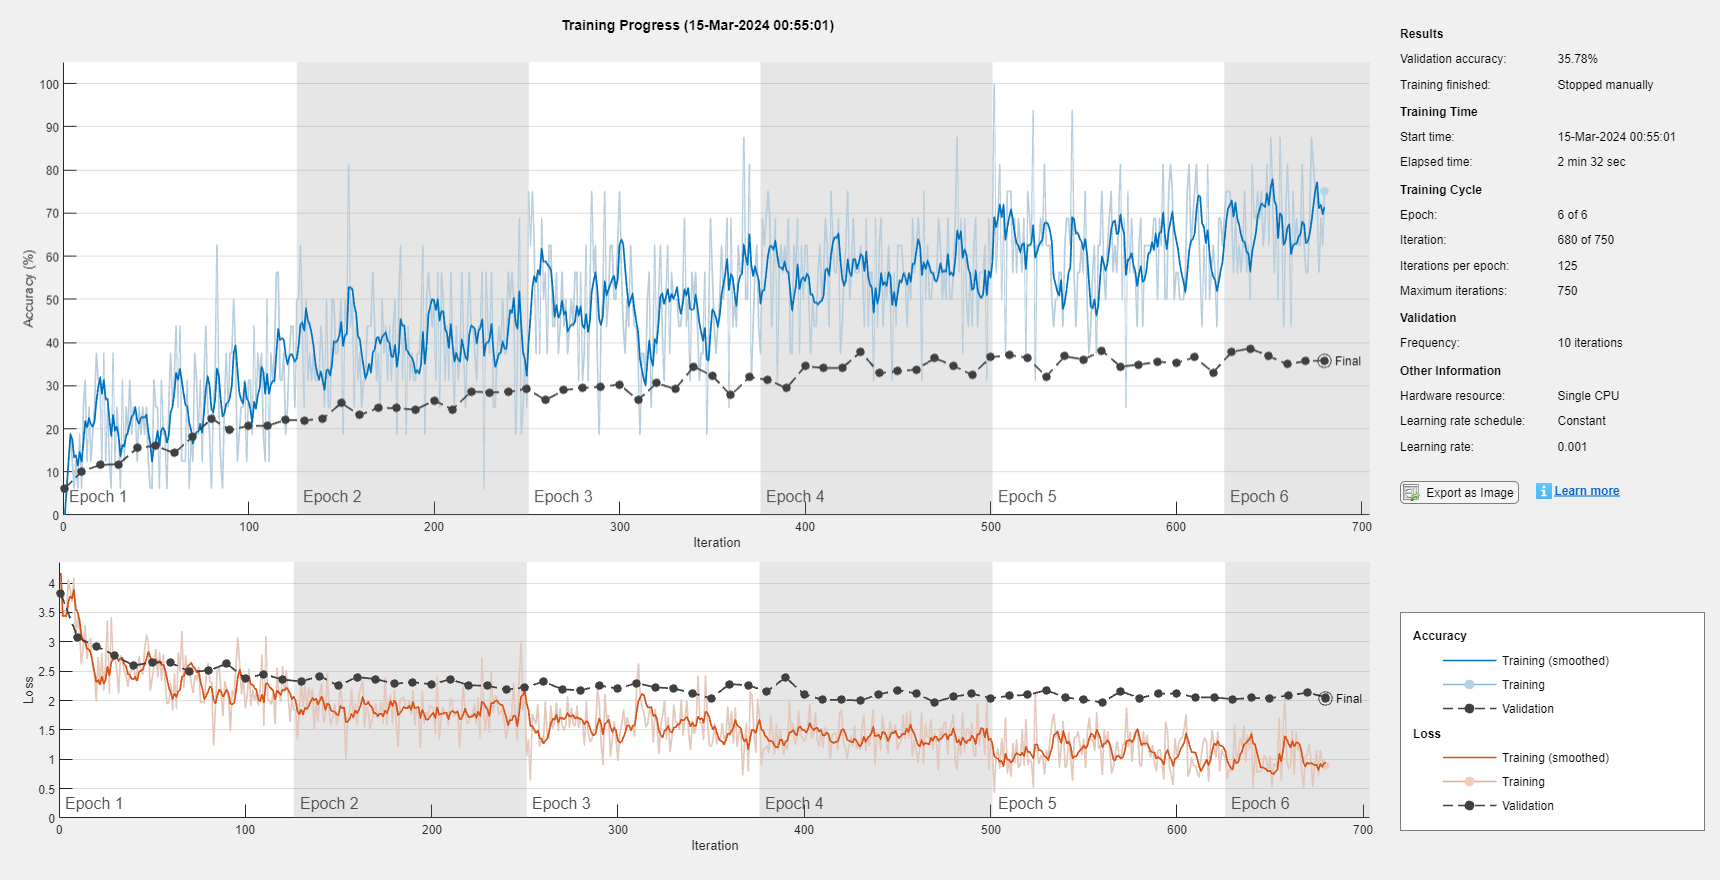

% training options 
options = trainingOptions('adam', ...
    "MiniBatchSize",16, ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',6, ...
    'Shuffle','every-epoch', ...
    'ValidationData',dsVal, ...
    'ValidationFrequency',10, ...
    'Verbose',true, ...
    'Plots','training-progress',...
    'ExecutionEnvironment','cpu');

% train network
net = trainNetwork(dsTrain,layers,options);

**Evaluate the image recognition system**

% classify the validation output using the trained network
[YPred,probs] = classify(net,dsVal);

% extract ground truth labels
YVal = imdsVal.Labels;

% accuracy in percent
accuracy = 100*sum(YPred == YVal)/numel(YVal);
disp(['The accuracy is: ' num2str(accuracy)])

The accuracy is: 35.7814


**Plot Confusion Matrix**

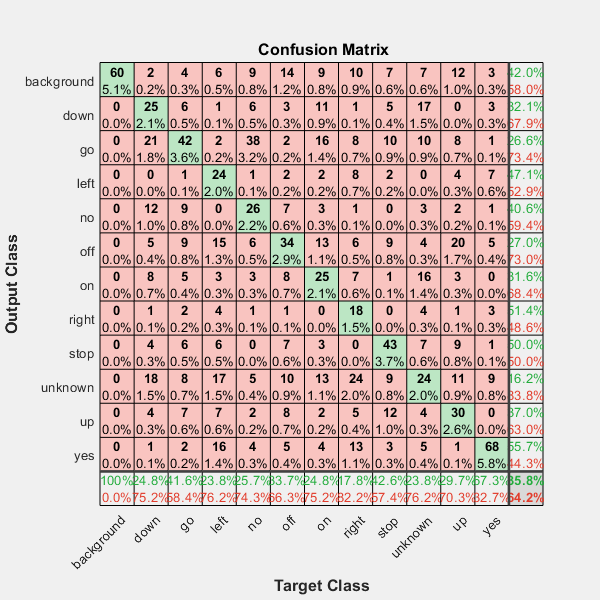

% plot confusion matrix
figure;
plotconfusion(YVal,YPred)